## Variables tuning

In this section there is the code configuration.

It is possible to setup what to print, the classifier version (matlab vs. liblinear) and the pretrained networks (AlexNet, ResNet and VGG16). 

%%% PRINT VARIABLES %%%
print_training_set = 0; % Print random images of the training set
print_test_set = 0; % Print random images of the predicted set

%%% CLASSIFICATION VERSION %%%
% classification_version = "matlab"; % Uncomment to use the matlab version of the svm classifier
classification_version = "liblinear"; % Uncomment to use the liblinear version of the svm classifier

%%% NETWORK SELECTION %%%
% network = "alexnet"; % Uncomment to use alexnet
network = "resnet"; % Uncomment to use resnet18
% network = "vgg" % Uncomment to use vgg16

## Load Data

Load the training and validation set as an image datastore. `imageDatastore` automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore lets you store large image data, including data that does not fit in memory. 

imdsTrain = imageDatastore('TrainingSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('ValidationSet','IncludeSubfolders',true,'LabelSource','foldernames');
numTrainImages = numel(imdsTrain.Labels);

### Print some images of the training set

In this section if the previous variable is true the code prints random training set images.

if print_training_set == 1
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i));
        imshow(I)
    end
end

## Load pretrained Network

Load the pretrained network based on the choice in the variable tuning

if network == "alexnet"
    net = alexnet;
elseif network == "resnet"
    net = resnet18;
else
    net = vgg16;
end

## Resize the images

The networks require different input size, in this section the image will be resized to fit the first input layer. To automatically resize the training and test images before they are input to the network, create augmented image datastores, specify the desired image size, and use these datastores as input arguments to `activations`.

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

## Select the activation layer for the feature extraction and extract the features

The network constructs a hierarchical representation of input images. Deeper layers contain higher-level features, constructed using the lower-level features of earlier layers. To get the feature representations of the training and test images, we will use `activations` on different layers depending on the network used. In our case for **alexnet** is **fc7**, for **resnet18** is **pool5** and for **vgg16** is **fc7**. This parameter can be changed. Basically we are extracting the feature from the layer before the layer that actually classify the things.

if network == "resnet"
    layer = 'pool5';
else
    layer = 'fc7';
end
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');
featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows');
YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;

## Classification Matlab version

Following the matlab tutorials on how to extract features there is the possibility to use the function *fitcecoc* to create a classifier and then generate the predictions. At the end it is possible to compute the accuracy.

if classification_version == "matlab"
    classifier = fitcecoc(featuresTrain,YTrain);
    YPred = predict(classifier,featuresTest);
    accuracy = mean(YPred == YTest);
end

## Classification liblinear version

In this section we use the liblinear library to use linears svm to perform the classification. In the first rows there's the conversion of the data to the one compatible to liblinear. Next we train the model passing the labels and the features. After we perform the prediction using the labels and the features of the test set and the model generated before. At the end we compute the accuracy.

if classification_version == "liblinear"
    YTrain = double(YTrain(:,1));
    YTest = double(YTest(:,1));
    featuresTrain = sparse(double(featuresTrain));
    featuresTest = sparse(double(featuresTest));
    model = train(YTrain, featuresTrain);
    YPred = predict(YTest, featuresTest, model);
    accuracy = mean(YPred == YTest)
end

..............................
optimization finished, #iter = 300
Objective value = -5.017809
nSV = 256

Switching to use -s 2

init f 5.686e+000 |g| 1.603e+002
iter  1 f 5.311e+000 |g| 2.860e+001 CG   9 step_size 1.00e+000 
..............................
optimization finished, #iter = 300
Objective value = -2.678001
nSV = 195

Switching to use -s 2

init f 2.855e+000 |g| 1.089e+002
iter  1 f 2.742e+000 |g| 1.308e+001 CG   9 step_size 1.00e+000 
..............................
optimization finished, #iter = 300
Objective value = -5.485412
nSV = 283

Switching to use -s 2

init f 6.013e+000 |g| 7.718e+001
..............................
optimization finished, #iter = 300
Objective value = -5.513782
nSV = 249

Switching to use -s 2

init f 6.260e+000 |g| 8.303e+001
..............................
optimization finished, #i

Accuracy = 91.6801% (2843/3101)


accuracy = 0.9168

## Show images

This portion of code shows 12 random images of the test set. For each of them it shows the number of the image, the prediction of the model and the correct class.

if print_test_set == 1
    idx = randi([1 3077],1,12);
    % idx = [];
    figure
    for i = 1:numel(idx)
        subplot(3,4,i)
        I = readimage(imdsTest,idx(i));
        label = YPred(idx(i));
        corr = YTest(idx(i));
        imshow(I)
        title("#: "+idx(i)+" / Predicted: "+label+" / Correct: "+corr)
    end
end

## Confusion Matrix

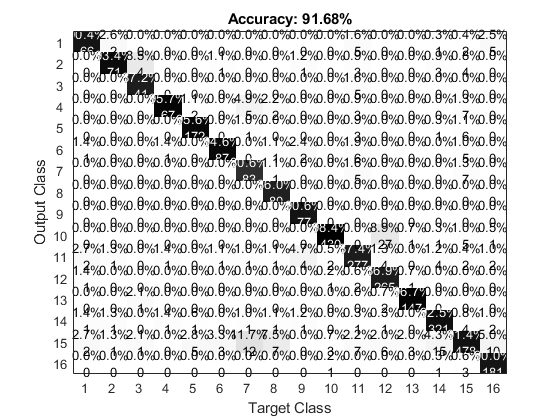

cm = confusionmat(YTest,YPred);
figure
plotConfMat(cm)